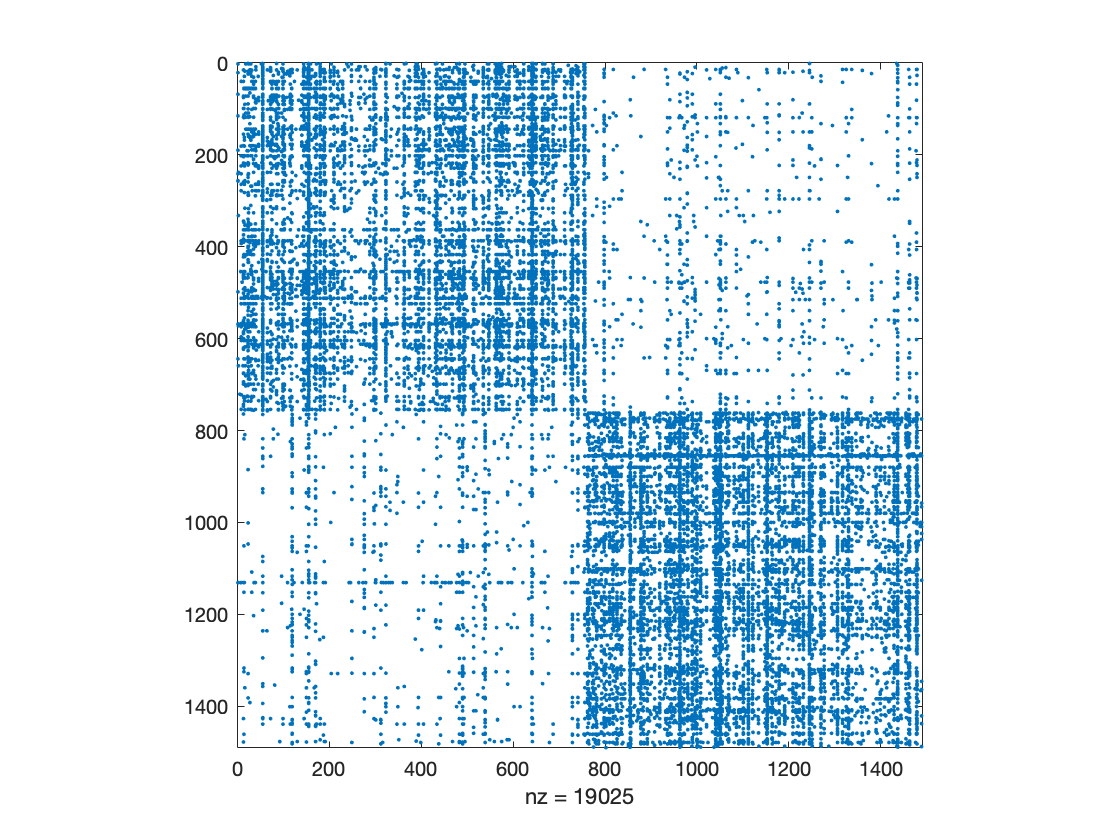

clear
%load("spectralGraphPartitioning-karate.mat");
load("spectraGraphPartitioning-polblogs.mat");
% load("spectralGraphPartitioning_circle_3.mat");
% load("spectralGraphPartitioning_circle_4.mat");

A = Problem.A;
spy(A);

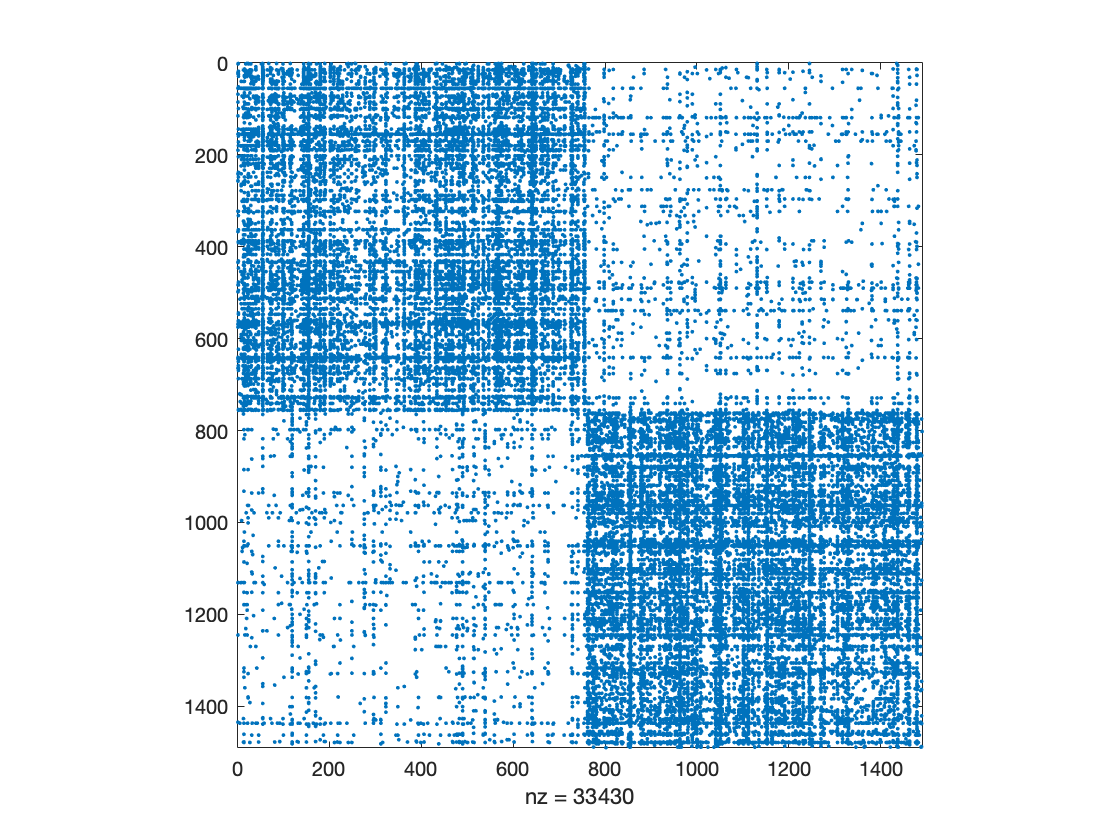


A;
A=A+A';
A=A-diag(diag(full(A)));
spy(A)

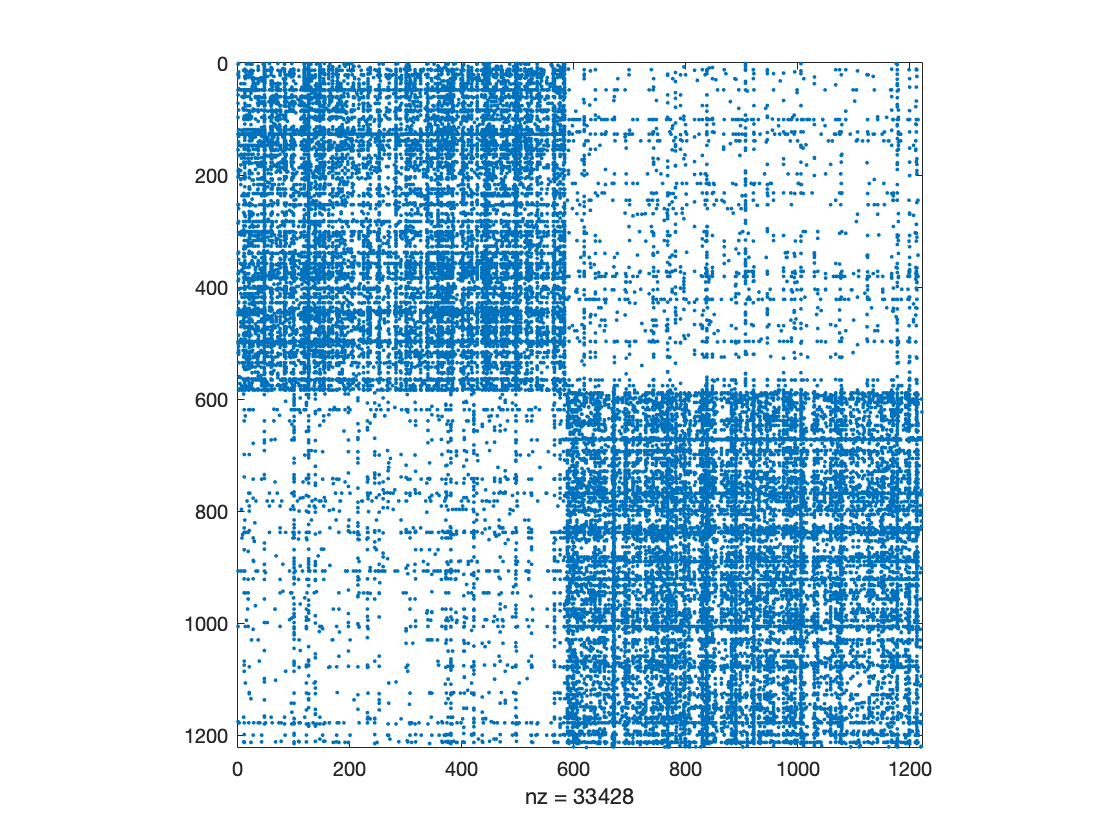

G=graph(A);
bins=conncomp(G);
ind=find(bins==1);
Gs=subgraph(G,ind);

Af=adjacency(Gs);
spy(Af)

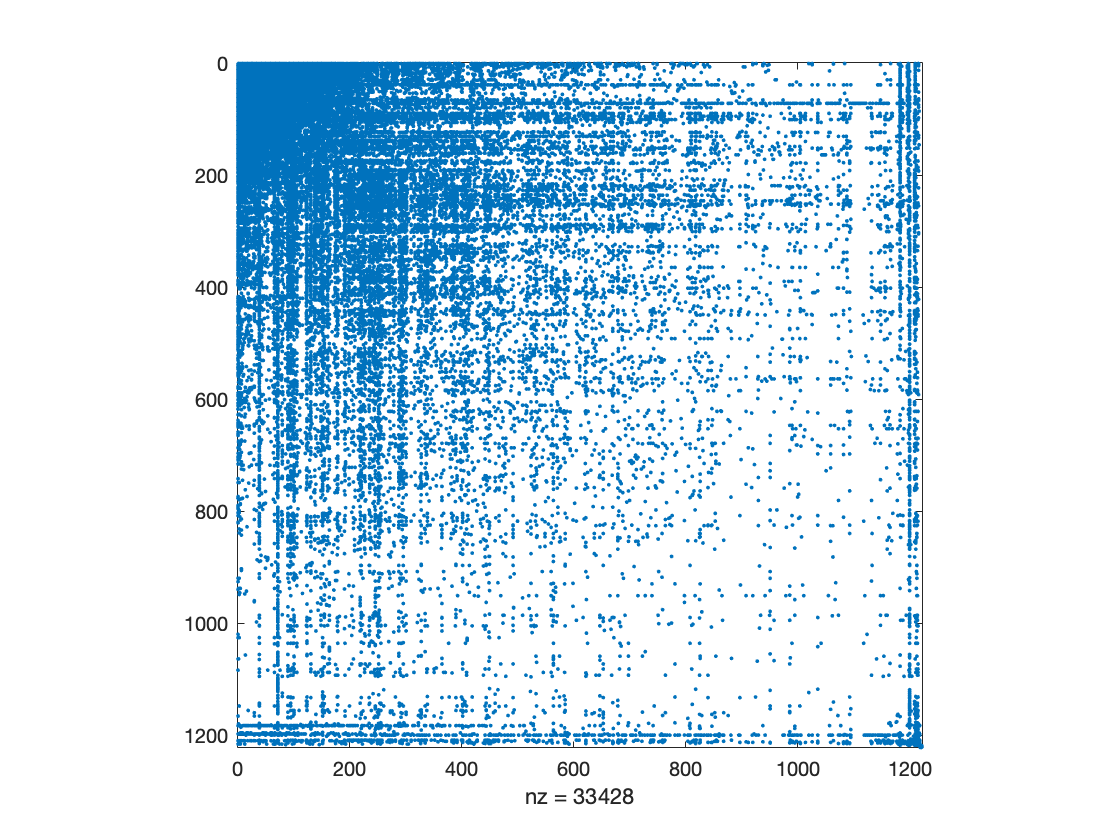


d = diag(Af*Af');
D = diag(d);
Dn = diag(d.^-(1/2));
L = full(D-Af);
Ln = Dn*L*Dn;
[V,e] = eig(Ln);
Fiedler = V(:,2);

P = speye(length(Fiedler));
[~,p] = sort(Fiedler,'ascend');
P = P(p,:);
Ap = P*Af*P';
spy(Ap);

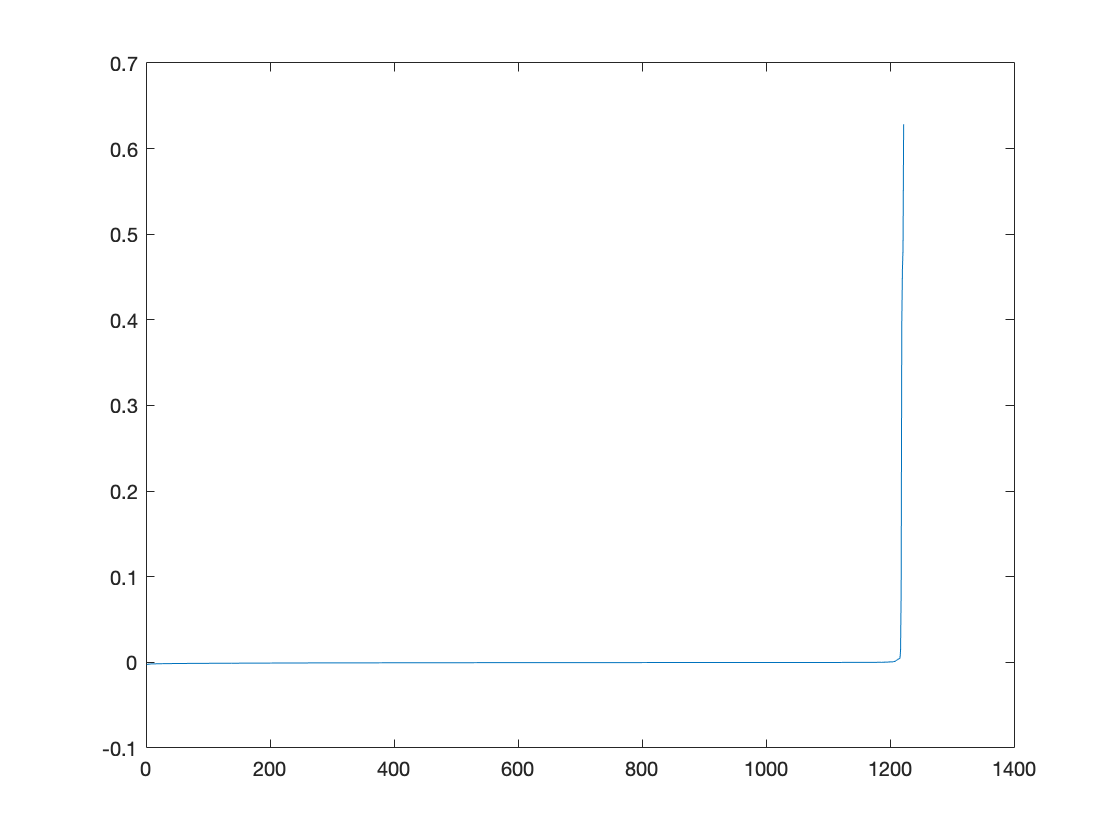


plot(Fiedler(p),'-');

% [~,n] = min(abs(Fiedler(p)))
% dp = P*d;
n=1180;

A1 = Af(1:n,1:n)

A1 =    (2,1)        1
  (19,1)        1
  (21,1)        1
  (48,1)        1
  (57,1)        1
  (72,1)        1
  (97,1)        1
 (127,1)        1
 (155,1)        1
 (192,1)        1
 (203,1)        1
 (204,1)        1
 (253,1)        1
 (286,1)        1
 (340,1)        1
 (376,1)        1
 (389,1)        1
 (445,1)        1
 (450,1)        1
 (497,1)        1
 (498,1)        1
 (500,1)        1
 (517,1)        1
 (907,1)        1
(1006,1)        1
(1176,1)        1
   (1,2)        1
  (16,2)        1
  (22,2)        1
  (26,2)        1
  (46,2)        1
  (48,2)        1
  (84,2)        1
 (119,2)        1
 (126,2)        1
 (127,2)        1
 (131,2)        1
 (141,2)        1
 (147,2)        1
 (165,2)        1
 (190,2)        1
 (197,2)        1
 (253,2)        1
 (260,2)        1
 (283,2)        1
 (303,2)        1
 (305,2)        1
 (338,2)        1
 (351,2)        1
 (372,2)        1
 (376,2)        1
 (386,2)        1
 (427,2)        1
 (428,2)        1
 (439,2)        1
 (441

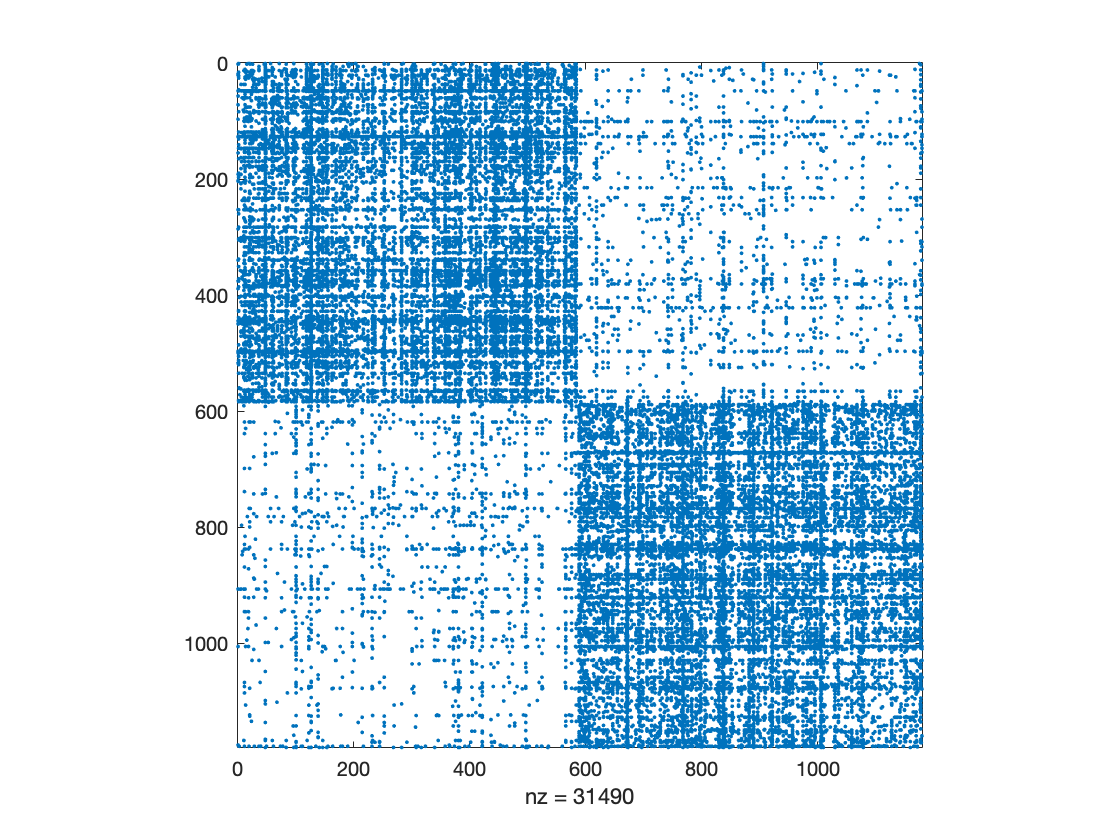

A1=A1+A1';
A1=A1-diag(diag(full(A1)));
spy(A1)

G1=graph(A1);
bins=conncomp(G1);
ind=find(bins==1)

ind =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


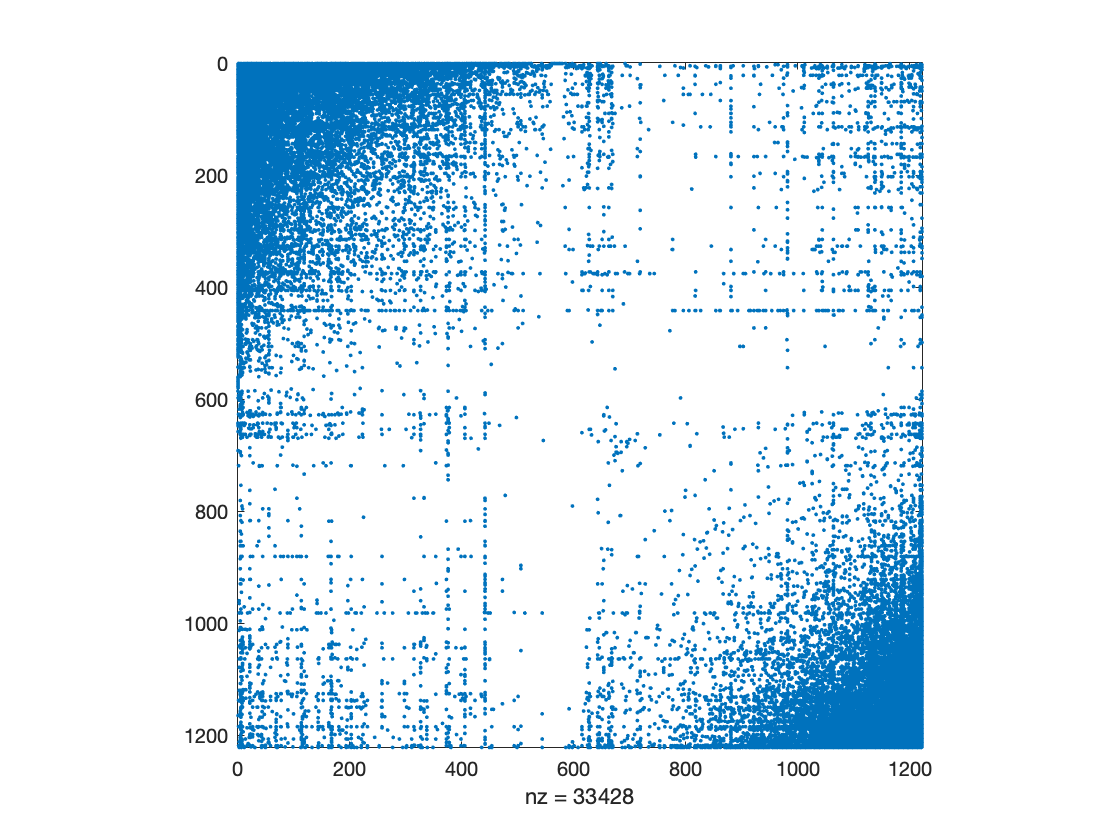

Gs1=subgraph(G1,ind);
Af1=adjacency(Gs);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
d1 = diag(Af1*Af1');
D1 = diag(d1);
Dn1 = diag(d1.^-(1/2));
L1 = full(D1-Af1);
Ln1 = Dn1*L1*Dn1;
[V1,e1] = eig(Ln1);
Fiedler1 = V1(:,3);

P1 = speye(length(Fiedler1));
[~,p1] = sort(Fiedler1,'descend');
P1 = P1(p1,:);
Ap1 = P1*Af1*P1';
spy(Ap1);

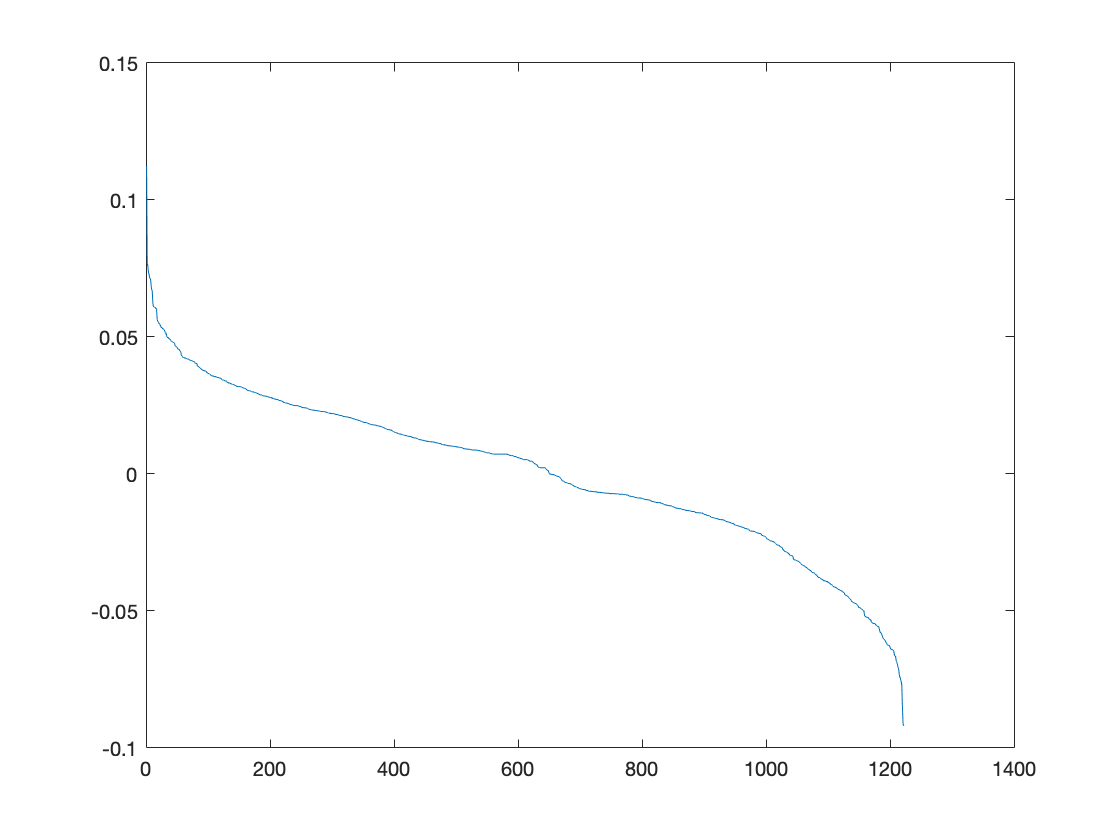


plot(Fiedler1(p1),'-');

[~,n1] = min(abs(Fiedler1(p1)))

n1 = 651

dp1 = P1*d1;

